## Controls Systems Textbook Example 10.6

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $\zeta\ge0.45,\ K_v\ge20$


$$L(s)=G_C(s)G(s)=\frac{K}{s(s+2)}$$


G = 1 / (s * (s + 2));   % type 1

### Design of a phase-lag compensator


$$K=\left|0-(-1+2j)\right|\times\left|-2-(-1+2j)\right|=5\\
K_{v,unc}=\frac{K}{2}=2.5\\
K_{v,comp}=\frac{z}{p}\cdot K_{v,unc}\\
\Rightarrow \frac{z}{p}=\alpha=8$$


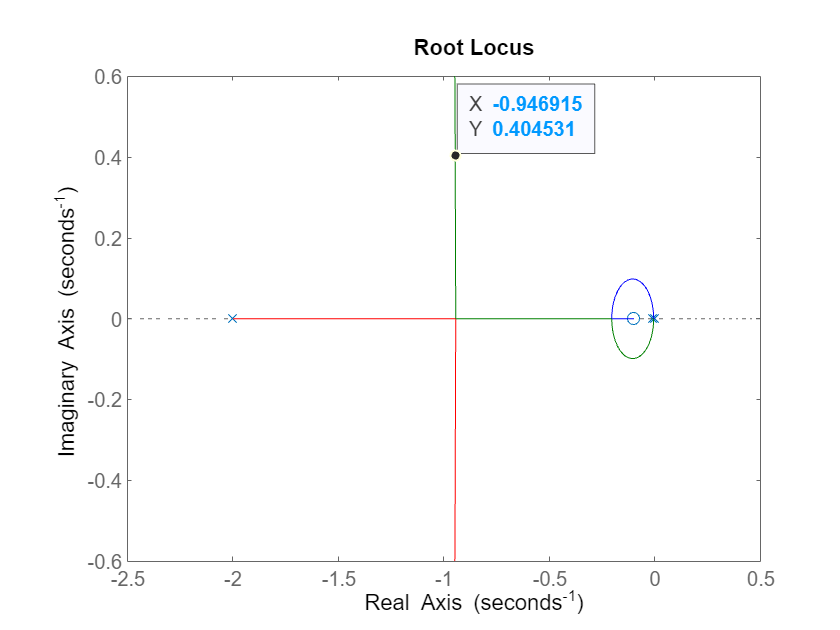

K = 5;
G_C = (s + .1) / (s + .0125);
rlocus(G_C * G)

T = feedback(K * G_C * G, 1);
stepinfo(T)

ans = struct with fields:
         RiseTime: 0.6674
    TransientTime: 5.8243
     SettlingTime: 5.8243
      SettlingMin: 0.9364
      SettlingMax: 1.2595
        Overshoot: 25.9491
       Undershoot: 0
             Peak: 1.2595
         PeakTime: 1.5922
